c1 = 1.21e-9

c1 = 1.2100e-09

c2 = 9.53e-10

c2 = 9.5300e-10

c3 = 1.78e-9

c3 = 1.7800e-09

c4 = 1.47e-9

c4 = 1.4700e-09

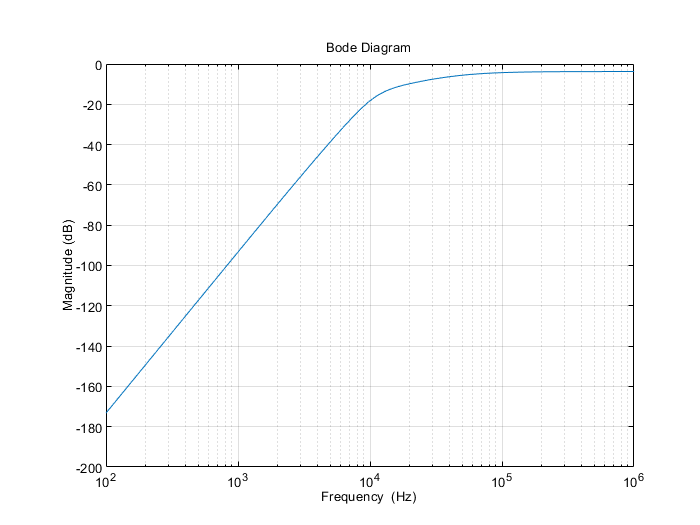


r1 = 11.3e3;
r2 = 12.7e3;
r3 = 10.2e3;
r4 = 4.87e3;

num4 = c2^2*c4^2;

denom0 = 1/(r1*r2*r3*r4);
denom1 = (c1+c2)/(r1*r3*r4) + (c3+c4)/(r1*r2*r3);
denom2 = (c3*c4)/(r1*r2) + (c1*c2)/(r3*r4) + (c1*c3 + c1*c4 + c2*c3 + c2*c4)/(r1*r3);
denom3 = (c1*c3*c4)/r1 + (c2*c3*c4)/r1 + (c1*c2*c3)/r3 + (c1*c2*c4)/r4;
denom4 = c1*c2*c3*c4;

options = bodeoptions;
options.FreqUnits = 'Hz';

transfer = tf([num4 0 0 0 0], [denom4 denom3 denom2 denom1 denom0]);
bodemag(transfer, options)
grid on